clear variables

%load and plot the data
load('lab6_1.mat')

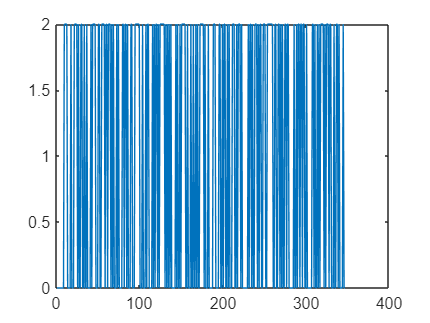


figure
plot(id.u);

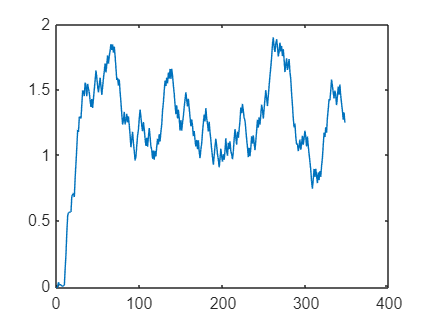

figure
plot(id.y);


na = 10;
nb = 10;

u = id.u;
y = id.y;

%build phi matrix for the linear regression
N = length(id.y);
phi = zeros(N, na+nb);

%we try to split the phi matrix into 2 matrices and build each one separately
%build the y elements
for i = 1:1:N
    for j = 1:1:na
        if (i <= j) %if the element is above or on the main diagonal
            phi(i,j) = 0;
        else %if the element is under the main diagonal
            phi(i,j) = -y(i-j);
        end
    end
end
% build the u elements
for i = 1:1:N
    for j = (na+1):1:(na+nb)
        if (i <= j-na) %if the element is above or on the main diagonal
            phi(i,j) = 0;
        else %if the element is under the main diagonal
            phi(i,j) = u(i-j+na);
        end
    end
end

## prediction

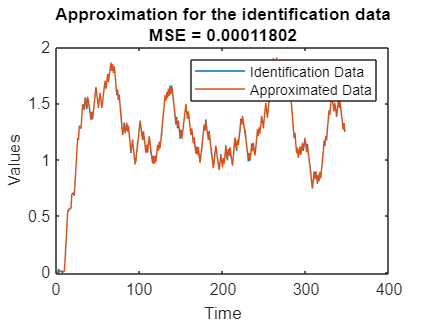

%find the approximation and plot it 
theta = phi \ y;

y_pred = phi * theta;

%calculate the MSE
err_squared_id = (y - y_pred) .^ 2;
MSE_id = (1/N) * sum(err_squared_id);

figure
plot(y);
hold on
plot(y_pred);
title("Approximation for the identification data"  + newline + "MSE = " + MSE_id)
legend("Identification Data", "Approximated Data");
xlabel('Time')
ylabel('Values')

## simulation

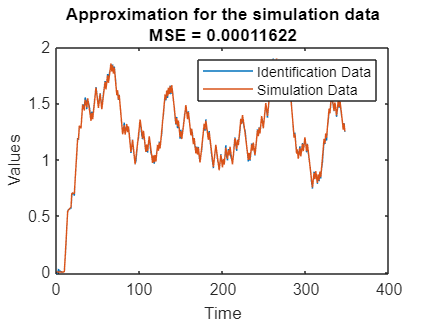

phi_sim = zeros(N, na+nb);

%calculate the simulation y by using the previous values

y_sim = zeros(N,1);

for i = 2:1:N
    %for the elements with y
    for j = 1:1:na
        if (i > j)
            phi_sim(i,j) = -y_sim(i-j);
        end
    end

    %for the elements with u
    for j = (na+1):1:(na+nb)
        if (i > j-na)
            phi_sim(i,j) = u(i-j+na);
        end
    end
%find the simulation data
y_sim(i) = phi_sim(i,:) * theta;
end

%calculating the simulation MSE 
err_squared_sim = (y - y_sim) .^ 2;
MSE_sim = (1/N) * sum(err_squared_sim);

%plot the simulation data
figure
plot(y)
hold on
plot(y_sim)
title("Approximation for the simulation data"  + newline + "MSE = " + MSE_sim)
legend("Identification Data", "Simulation Data");
xlabel('Time')
ylabel('Values')